Distribution Shape for OR

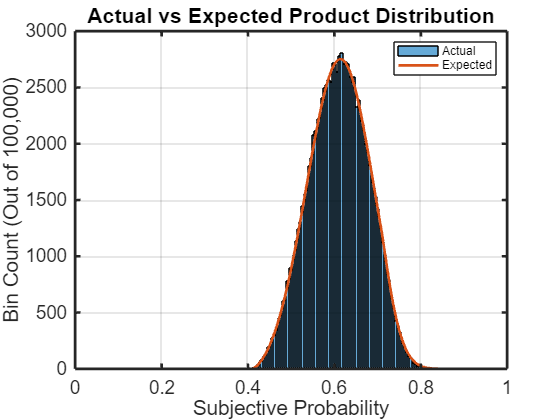

center1 = .34;
spread1 = .06;
center2 = .41;
spread2 = .1;

pdf1 = @(p) modified_beta(p,center1,spread1);
pdf2 = @(p) modified_gaussian(p,center2,spread2);
inverse_cdf1 = @(p) modified_beta_inverse_cdf(p,center1,spread1);
inverse_cdf2 = @(p) modified_gaussian_inverse_cdf(p,center2,spread2);

% Combine the Events
disjunction_density = @(z) integral(@(p) pdf1(p).*pdf2((z-p)./(1-p))./(1-p),0,1);

% Check That This Is The Product Distribution
pdf1_values = inverse_cdf1(rand(1,100000));
pdf2_values = inverse_cdf2(rand(1,100000));
disjunction_values = pdf1_values + pdf2_values - pdf1_values.*pdf2_values;
h = histogram(disjunction_values);
hold on
x_mesh = 0:.001:1;
disjunction_densities = nan(1,length(x_mesh));
for index = 1:length(x_mesh)
    disjunction_densities(index) = disjunction_density(x_mesh(index));
end
A = h.BinWidth*1e5;
plot(x_mesh,A*disjunction_densities)
title('Actual vs Expected Product Distribution')
xlabel('Subjective Probability')
ylabel('Bin Count (Out of 100,000)')
legend({'Actual','Expected'})
sexy_plot
hold off

% Checking Equation 

for index = 1:7
    fprintf('On Trial %i/%i\n',index,30)
    center1 = .4+index/200;
    spread1 = .04;
    center2 = .4+.2*rand;
    spread2 = .04+.1*rand;

    pdf1 = @(p) modified_beta(p,center1,spread1);
    pdf2 = @(p) modified_gaussian(p,center2,spread2);
    inverse_cdf1 = @(p) modified_beta_inverse_cdf(p,center1,spread1);
    inverse_cdf2 = @(p) modified_gaussian_inverse_cdf(p,center2,spread2);

    % Mean of Product Distributions
    mean1 = integral(@(p) p.*pdf1(p),0,1,'ArrayValued',true);
    mean2 = integral(@(p) p.*pdf2(p),0,1,'ArrayValued',true);

    % Variance of Product Dsitributions
    variance1 = integral(@(p) power(p-mean1,2).*pdf1(p),0,1,'ArrayValued',true);
    variance2 = integral(@(p) power(p-mean2,2).*pdf2(p),0,1,'ArrayValued',true);

    % Combine the Events
    disjunction_density = @(z) integral(@(p) pdf1(p).*pdf2((z-p)./(1-p))./(1-p),0,1);

    % Mean and Variance of Resulting Distribution
    dx = .0001;
    x_mesh = 0:dx:1;
    disjunction_densities = nan(1,length(x_mesh));
    for counter = 1:length(x_mesh)
        disjunction_densities(counter) = disjunction_density(x_mesh(counter));
    end
    disjunction_mean = sum(x_mesh.*disjunction_densities)*dx
    disjunction_variance = sum(power(x_mesh-disjunction_mean,2).*disjunction_densities)*dx;
    disjunction_standard_deviation = sqrt(disjunction_variance)


    % Expected Results as per Decentralizing the Odds
    expected_mean = mean1+mean2-mean1*mean2
    expected_variance = variance1*variance2+variance1*power(1-mean2,2)+variance2*power(1-mean1,2);
    expected_standard_deviation = sqrt(expected_variance)
end

On Trial 1/30


disjunction_mean = 0.6531

disjunction_standard_deviation = 0.0419

expected_mean = 0.6531

expected_standard_deviation = 0.0419

On Trial 2/30


disjunction_mean = 0.6905

disjunction_standard_deviation = 0.0611

expected_mean = 0.6905

expected_standard_deviation = 0.0611

On Trial 3/30


disjunction_mean = 0.7319

disjunction_standard_deviation = 0.0472

expected_mean = 0.7319

expected_standard_deviation = 0.0472

On Trial 4/30


disjunction_mean = 0.6663

disjunction_standard_deviation = 0.0510

expected_mean = 0.6663

expected_standard_deviation = 0.0510

On Trial 5/30


disjunction_mean = 0.6654

disjunction_standard_deviation = 0.0609

expected_mean = 0.6654

expected_standard_deviation = 0.0609

On Trial 6/30


disjunction_mean = 0.7042

disjunction_standard_deviation = 0.0652

expected_mean = 0.7042

expected_standard_deviation = 0.0652

On Trial 7/30


disjunction_mean = 0.6816

disjunction_standard_deviation = 0.0522

expected_mean = 0.6816

expected_standard_deviation = 0.0522

On Trial 8/30


disjunction_mean = 0.6741

disjunction_standard_deviation = 0.0322

expected_mean = 0.6741

expected_standard_deviation = 0.0322

On Trial 9/30
